# Teste Sistema Mecânico (dinâmico) mola-massa sem amortecimento

22/04/2021  Arménio Correia   armenioc@isec.pt

   10/05/2022 - João Choupina Ferreira da Mota - 2020151878

   10/05/2022 - Ricardo Almeida de Aguiar Tavares - 2021144652

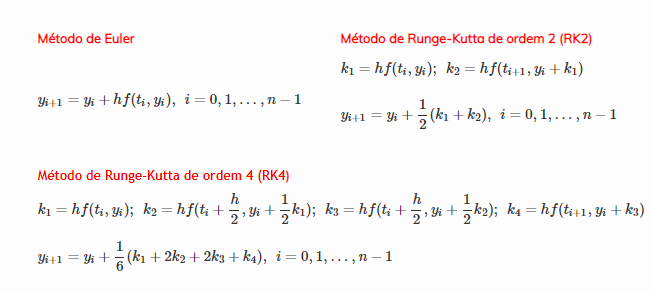

syms u(t) v(t)

f =@(t,u,v) v;
g =@(t,u,v) -16*u;
a = 0;
b = 4;
n = 100;
u0 = 9;
v0 = 0;

eqns = [diff(u,t)==v,diff(v,t)==-16*u];
ci = [u(0)==u0,v(0)==v0];
[sExataU,sExataV] = dsolve(eqns,ci);

h =@(t) eval(vectorize(char(sExataU)));


[t,uEuler,~] = NEulerSED(f,g,a,b,n,u0,v0);
[~,uRK2,~] = NRK2SED(f,g,a,b,n,u0,v0);
[~,uEulerM,~] = NEulerMelhoradoSED(f,g,a,b,n,u0,v0);
[~,uRK4,~] = NRK4SED(f,g,a,b,n,u0,v0);

uExata = h(t);

erroEuler = abs(uExata-uEuler);
erroRK2 = abs(uExata-uRK2);
erroEulerM = abs(uExata-uEulerM);
erroRK4 = abs(uExata-uRK4);


array2table([t.',uExata.', uEuler.',uRK2.',uEulerM.',uRK4.',erroEuler.',erroRK2.',erroEulerM.',erroRK4.'],...
            "VariableNames",{'t','Exata','Euler','RK2','Euler Melhorado','RK4','erroEuler','erroRK2','erroEulerM','erroRK4'})

ans = 101×10 table
     t       Exata      Euler       RK2       Euler Melhorado      RK4       erroEuler     erroRK2      erroEulerM     erroRK4  
    ____    _______    _______    ________    _______________    ________    _________    __________    __________    __________

       0          9          9           9              9               9           0              0             0             0
    0.04      8.885          9      8.8848         8.8848           8.885     0.11495     0.00024555    0.00024555    2.0962e-07
    0.08     8.5431     8.7696      8.5407         8.5407          8.5793     0.22648      0.0024442     0.0024442       0.0

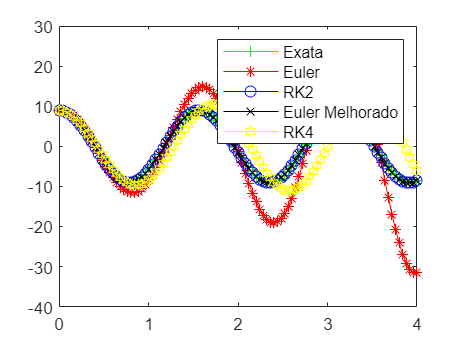


plot(t,uExata,"-g+")
hold on
plot(t,uEuler,"-r*")
plot(t,uRK2,"-bo")
plot(t,uEulerM,"-blackx")
plot(t,uRK4,"-yh")
hold off
legend("Exata","Euler","RK2","Euler Melhorado","RK4")